# **第八章 卷积神经网络**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **8.1 卷积神经网络简介**

        如图1所示，2018年，享有计算机领域诺贝尔奖美誉的“图灵奖”授予了Yann Lecun、Geoffrey Hinton和Yoshua Bengio三位科学家，以表彰他们在深度学习模型方面的原创性工作和卓越贡献。

领域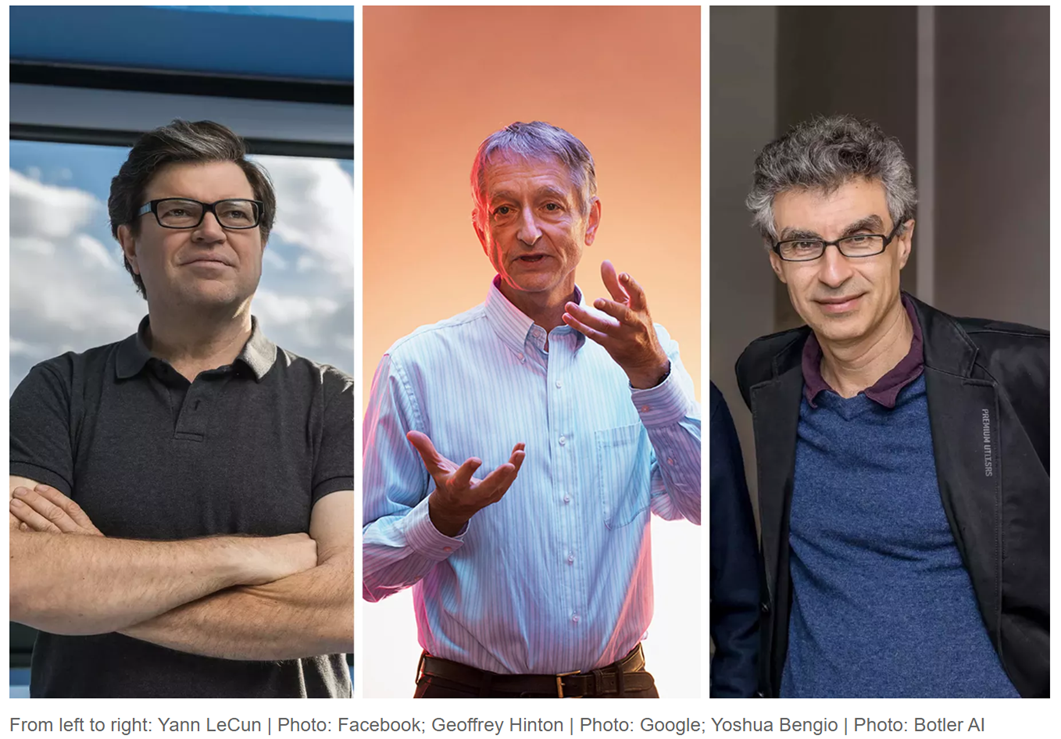

图1 2018年图灵奖得主

        并不是将一个传统的前向神经网络的隐含层增加到几十层，或是几百层，就自然而然变成了一个深度神经网络。那么怎样的神经网络可以称之为深度神经网络呢？图2描述了机器学习模型与深度学习模型的主要区别：

- **机器学习模型：**特征提取（Feature extraction）由人工参与完成，模型的泛化性能很大程度上依赖特征提取的好坏，特征提取环节充分体现了人类的先验知识。在许多领域里，模型性能的不断提升，都与特征提取的改善有着密切的联系。

- **深度学习模型：**特征提取不需要人工参与，由模型自身完成，省掉了我们的不少工作。然而，遗憾的是，深度学习模型提取出的特征均为抽象特征，没有明确的物理意义，导致我们人类是看不懂的。因此，如何对抽象特征进行可视化并予以解释，是深度学习领域非常热门一个研究方向。

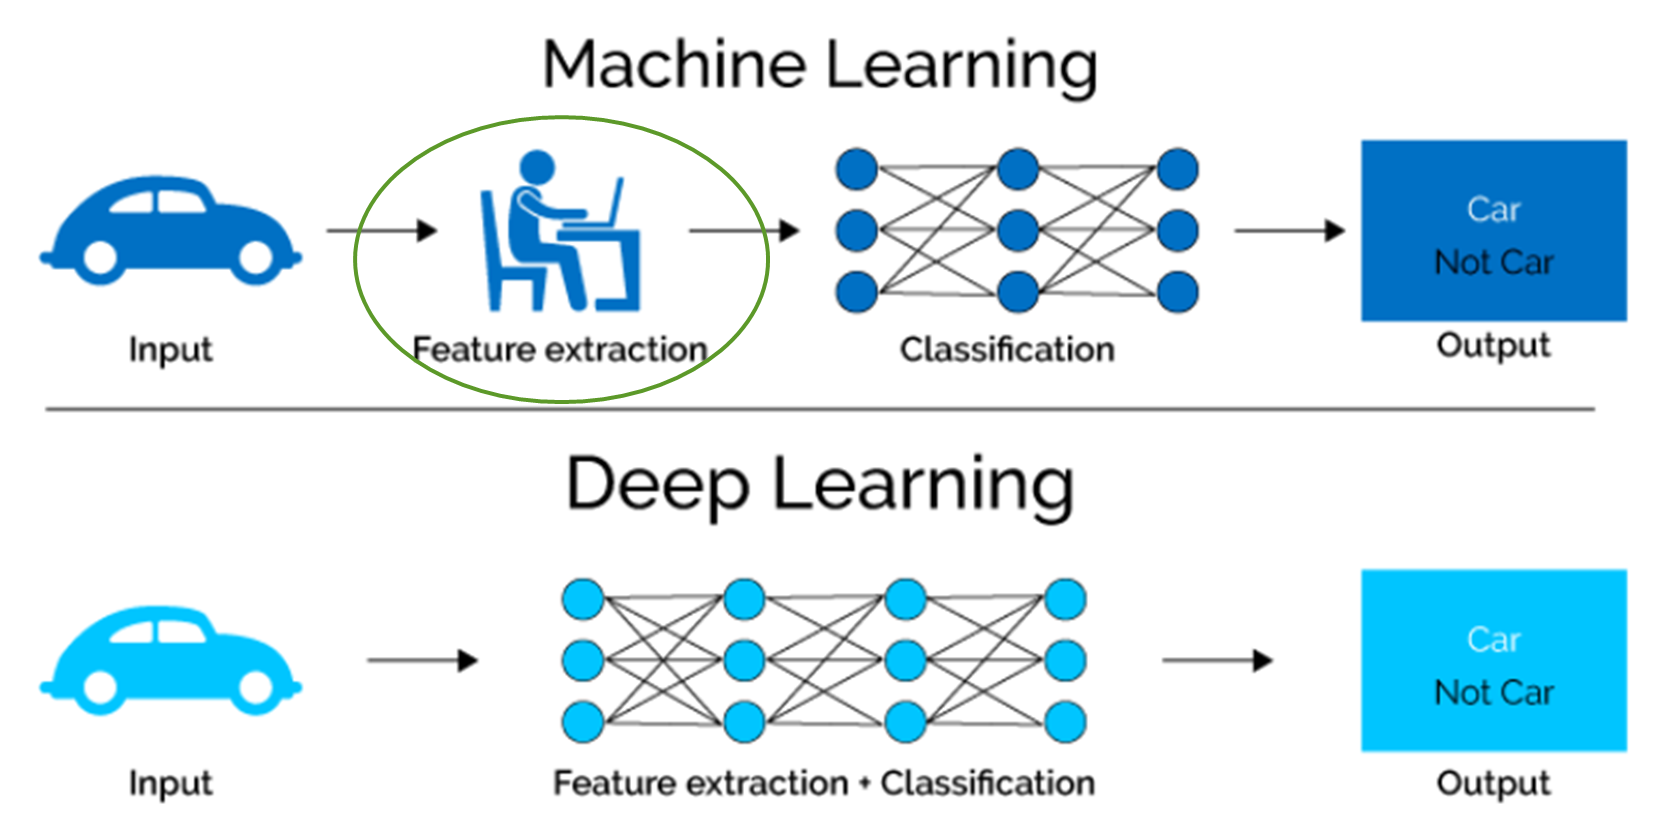

图2 机器学习与深度学习的区别

        卷积神经网络（Convolutional Neural Networks, CNNs）是一种在计算机视觉和图像处理领域广泛使用的深度学习模型。它的核心思想是通过模仿人类视觉系统的工作原理来处理图像数据。卷积神经网络的拓扑结构如图3所示，主要由三部分组成：

- **输入层（Input Layer）：**仅包含一层，实现将图像数据（黑白、灰度和彩色图像均可）输入到模型中。

- **特征提取层（Feature Extraction Layers）：**包含多层（卷积层、池化层、激活函数层、归一化层等），实现从不同的角度提取输入图像数据中的特征。

- **全连接层（Fully Connected Layers）：**包含多层（层与层之间均采用全连接的方式），实现将提取的特征映射到模型的输出（譬如：类别标签）。

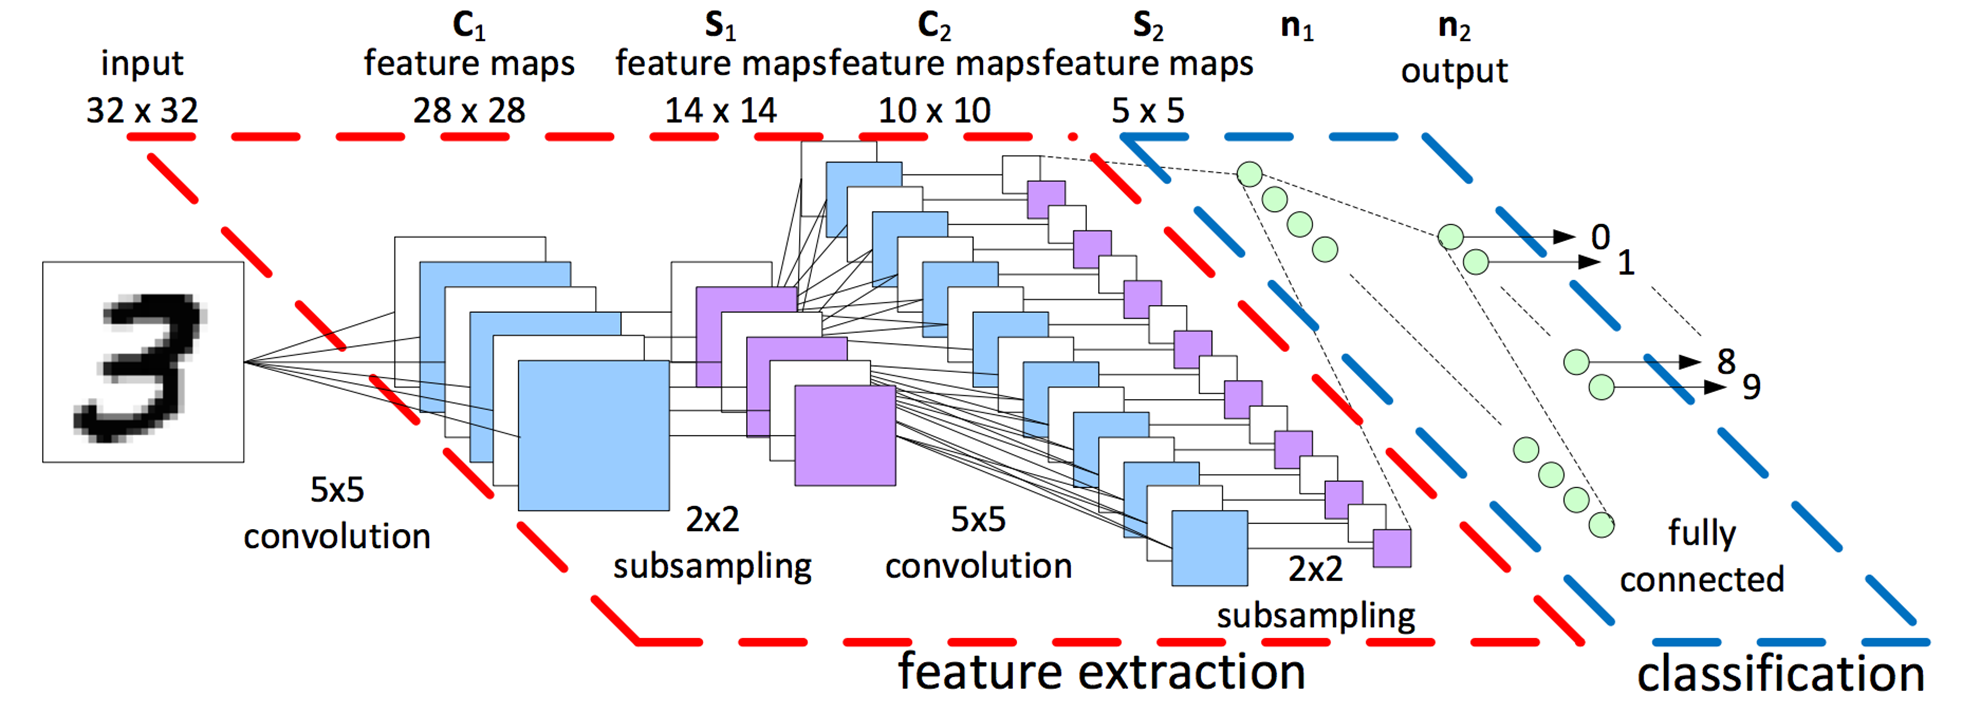

图3 卷积神经网络的拓扑结构

        卷积神经网络中三个最重要的操作：卷积（Convolution）、池化（Pooling）和展平（Flatten），接下来详细介绍她们的工作原理：

- **卷积运算**

        如图4所示，原始图像的尺寸为6*6，卷积核的尺寸为3*3。卷积运算开始后，卷积核从原始图像的左上角出发，每做完一次卷积，卷积核按照规定的步长向右移动，来到一个新的位置后，再执行一次卷积运算。如此重复，当卷积核移动到原始图像的右边界时，卷积核按照规定的步长向下移动，还是从原始图像的左侧向右侧移动，直至卷积核来到原始图像的右下角，完成最后一次卷积运算。

        当卷积核与原始图像某个Patch重合时，卷积运算的规则特别简单：对应位置元素相乘再相加。譬如：当卷积核处于原始图像左上角时，卷积运算结果计算如下：

1*0 + 3*1 + 5*0 + 3*1 + 5*0 + 7*1 + 5*0 + 7*1 + 9*0 = 20

其它位置的计算过程以此类推。经卷积运算后，得到的结果称之为特征图（Feature Map），从图4中可以看出，当卷积核移动的步长为1时，特征图的维度为4*4（读者不妨算一下，若卷积核移动步长为2时，特征图的维度是多少呢？答案是2*2）。

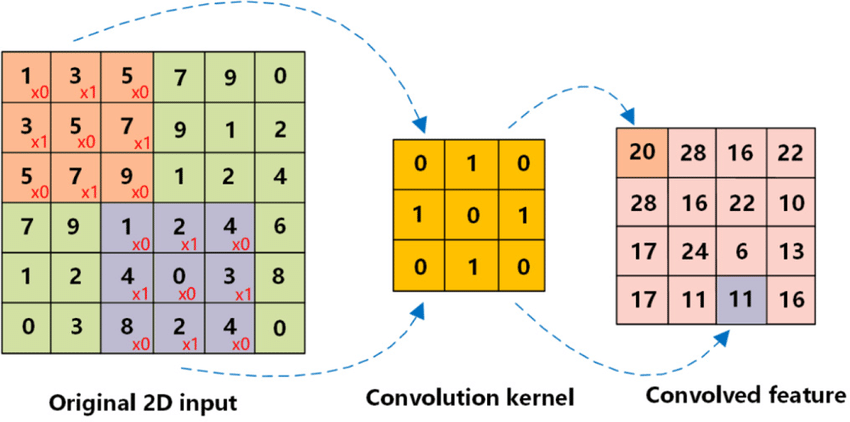 

图4 卷积运算示意图

        若卷积核的移动步长≥2，当卷积核移动到原始图像的最右端或最下端时，可能会出现若干列/行没有被卷积到的情况，造成信息的丢失。此外，还有另外一个情况，有些场景下我们希望卷积后得到的特征图尺寸与原始图像的尺寸保持一致。为了解决上述两个问题，需要用到补零（Zero Padding）操作，如图5所示。一般情况下，补零操作采取的是对称补零的方式，即上下左右同时各补上若干行或若干列零。

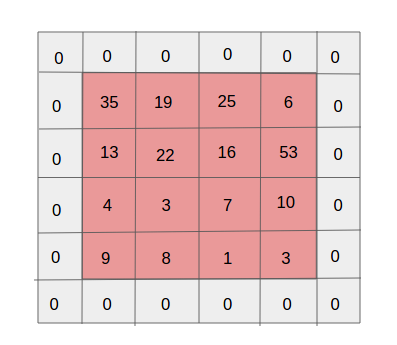

图5 补零（Zero Padding）操作示意图

- **池化运算**

        池化运算的主要目的是为了降维，类似于卷积运算，池化运算中同样需要事先定义池化核的尺寸和移动步长。如图6所示，当池化核的尺寸为2*2，移动步长也为2时，原始4*4的图像经池化运算后得到的特征图维度是2*2（读者不妨思考一下，若池化核的移动步长为1，那么经池化后得到的特征图维度是多少呢？答案是3*3）。

        如图6所示，通常情况下，池化运算有两种方式：

- **最大池化（Max Pooling）：**将每个Patch中的最大元素保留，其余元素删除；

- **平均池化（Average Pooling）：**将每个Patch中的所有元素计算平均值。

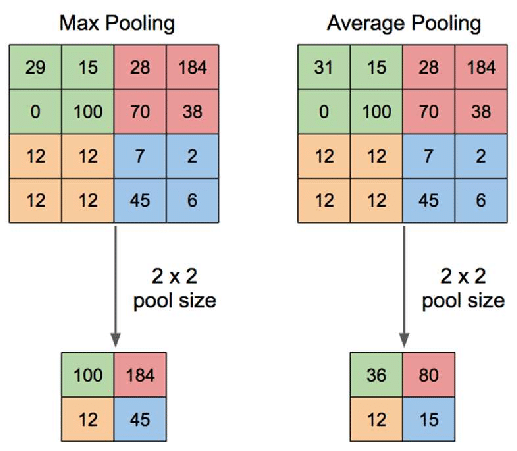

图6 池化运算示意图

- **展平操作**

        如图7所示，展平操作就是将特征图转换为向量的形式，准备送入后面的全连接层。 

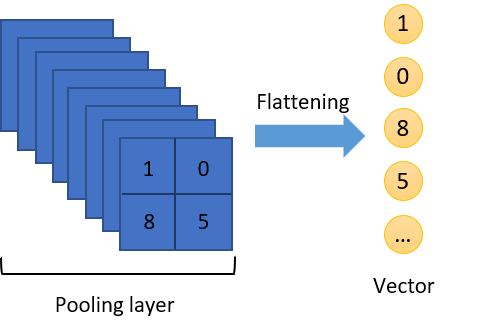

图7 展平操作示意图

        如图8所示，一张输入为28*28*1的原始图像，在卷积神经网络中前向传播的具体过程如下：

- **第一个卷积层：**假设该层一共有n1个不同的卷积核，每个卷积核的尺寸是5*5*1（卷积核有一个叫做“深度”的概念，由前一层的输出的通道数决定，在这里，因输入层的图像为黑白图像，通道数为1，所以卷积核的深度也为1；若输入层的图像为彩色图像，即通道数为3，那么卷积核的尺寸应该是5*5*3），当卷积核的移动步长为1时，该层的输出特征图维度是24*24*n1。

- **第一个池化层：**假设池化核的尺寸为2*2，池化核的移动步长也为2，那么经过该层后，输出的特征图维度将缩小一半，即12*12*n1（通道数不会改变）。

- **第二个卷积层：**假设该层一共有n2个不同的卷积核，每个卷积核的尺寸为5*5*n1（因前一层输出的特征图通道数为n1），当卷积核的移动步长为1时，该层的输出特征图维度是8*8*n2。具体的计算过程如图9所示，两个深度相同的数据立方体先按照通道依次卷积，最后再把相同位置的结果累加到一起即可。

- **第二个池化层：**与第一个池化层一样，假设池化核的尺寸为2*2，池化核的移动步长也为2，那么经过该层后，输出的特征图维度将缩小一半，即4*4*n2。

- **展平层：**该层的作用就是把上一层输出的数据立方体变成一个列向量，维度是（16n2*1）。

- **全连接层：**假设该层的神经元个数为n3，那么经过该层后，输出的向量维度将是n3*1。

- **输出层：**因该模型是手写数字识别模型，一共0-9这10个数字，所以输出层的神经元数量是10。

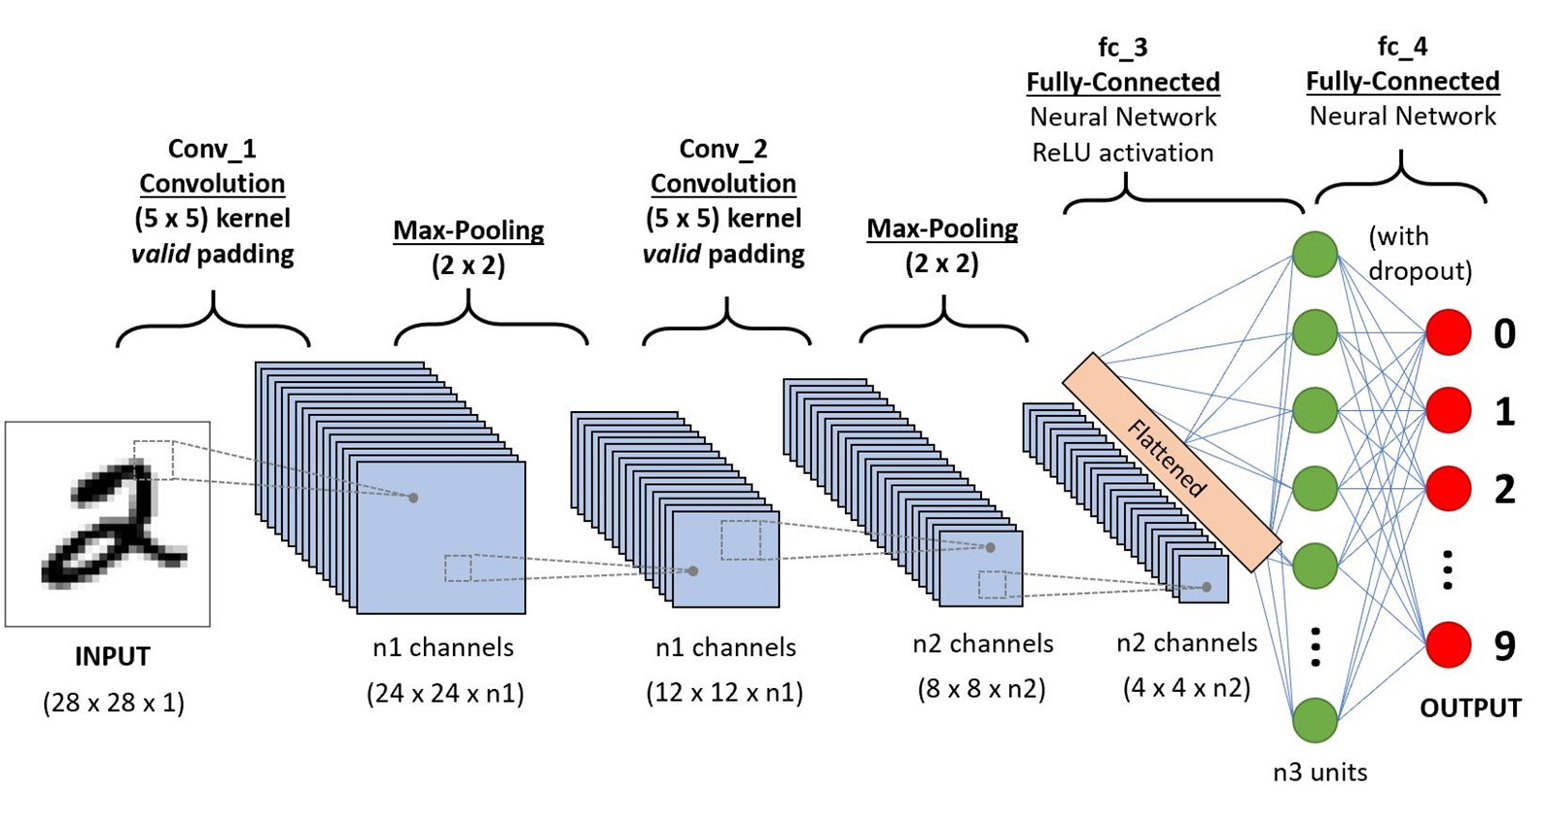

图8 卷积神经网络前向传播过程

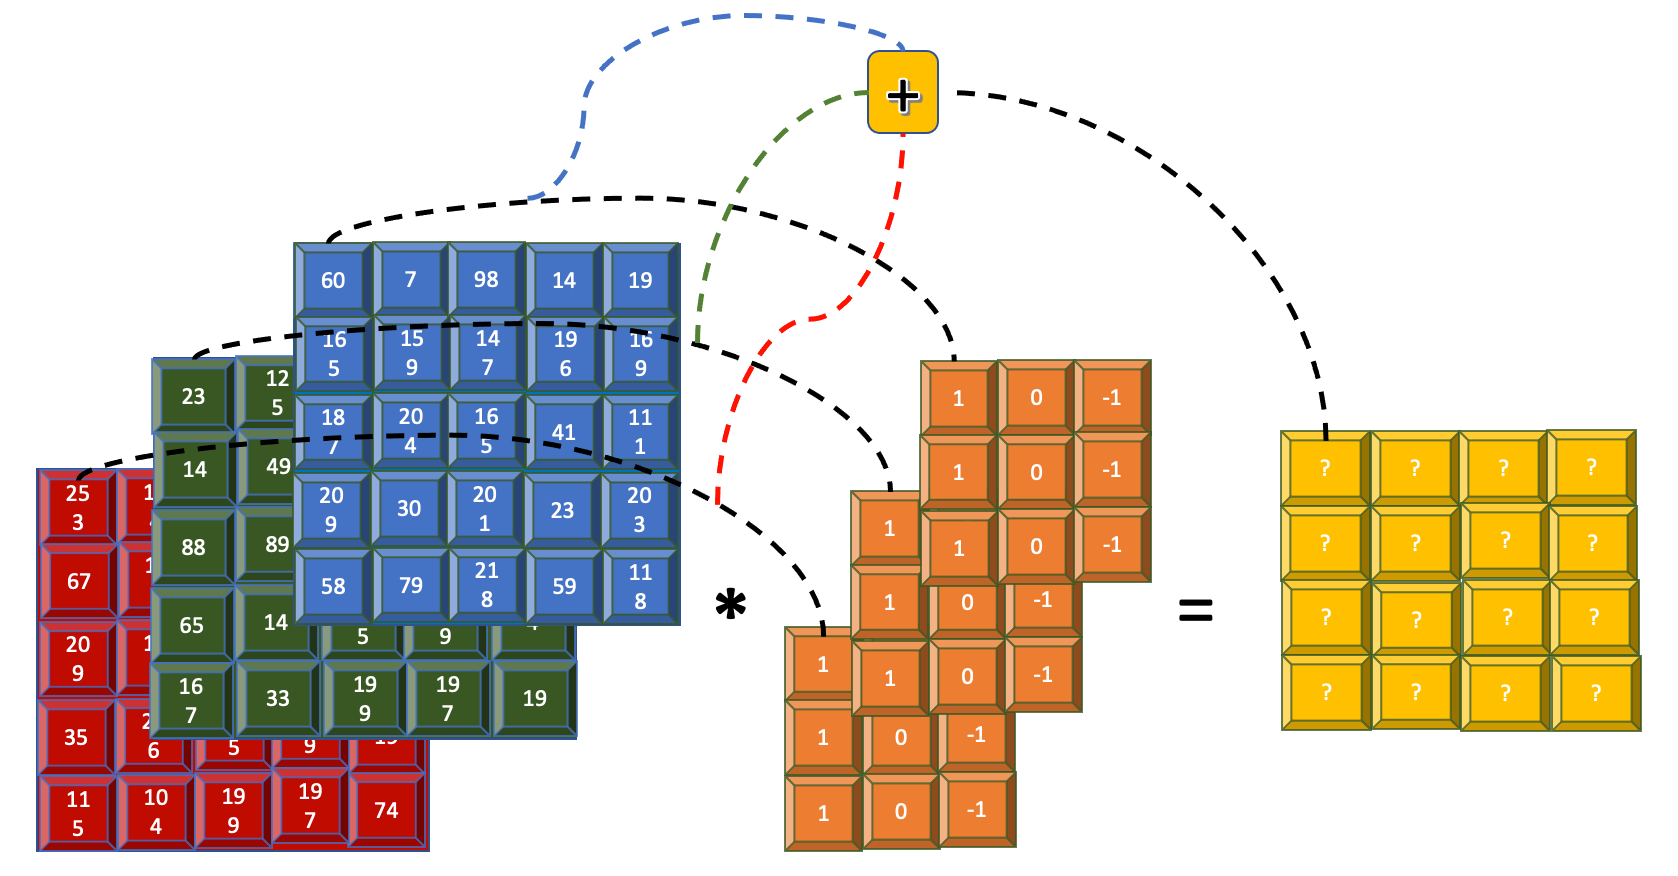

图9 多通道卷积运算示意图

        对应的，图8所示的卷积神经网络模型中一共包含的参数量如下：

- **第一个卷积层：**该层一共有n1个不同的卷积核，每个卷积核的尺寸是5*5*1，因此，该层的卷积核参数量为：5*5*1*n1。此外，类似于BP神经网络里的阈值概念，这里每个卷积核也有一个阈值。所以，该层的总参数量为：5*5*1*n1 + n1。

- **第一个池化层：**该层的池化核尺寸与移动步长均为由用户定义的超参数，该层不包含任何需要训练的参数。

- **第二个卷积层：**该层一共有n2个不同的卷积核，每个卷积核的尺寸为5*5*n1，因此，该层的卷积核参数量为：5*5*n1*n2。再加上每个卷积核的一个阈值，所以，该层的总参数量为：5*5*n1*n2 + n2。

- **第二个池化层：**与第一个池化层一样，该层也不包含任何需要训练的参数。

- **展平层：**该层的作用就是实现维度的变换，也不涉及任何需要训练的参数。

- **全连接层：**该层的神经元个数为n3，展平层与该层之间采取全连接方式，连接权值的数量为：4*4*n2*n3。再加上每个神经元的一个阈值，所以，该层的总参数量为：4*4*n2*n3 + n3。

- **输出层：**该层的神经元数量为10，全连接层与该层之间采取全连接方式，连接权值的数量为：n3*10。再加上每个神经元的一个阈值，所以，该层的总参数量为：n3*10 + 10。

        图10展示了经典的AlexNet模型的拓扑结构，以及前向传播经过各层时输出的特征图维度，以及各个卷积层和全连接层上的参数数量。细心的读者不难发现，尽管AlexNet模型的总参数量为60965128，但绝大多数（约96.17%）的参数都来自于最后三层全连接层。而前面卷积层的层数尽管较多，但参数量相对而言要少很多，这是因为卷积运算中有一个非常重要的机制：参数共享，即卷积核在整张图像推扫的过程中，其参数是共享、固定不变的。

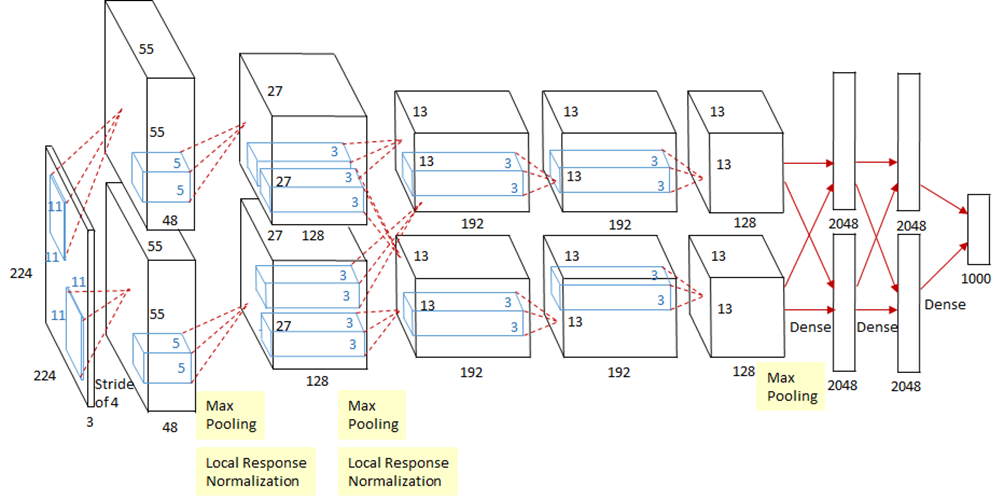 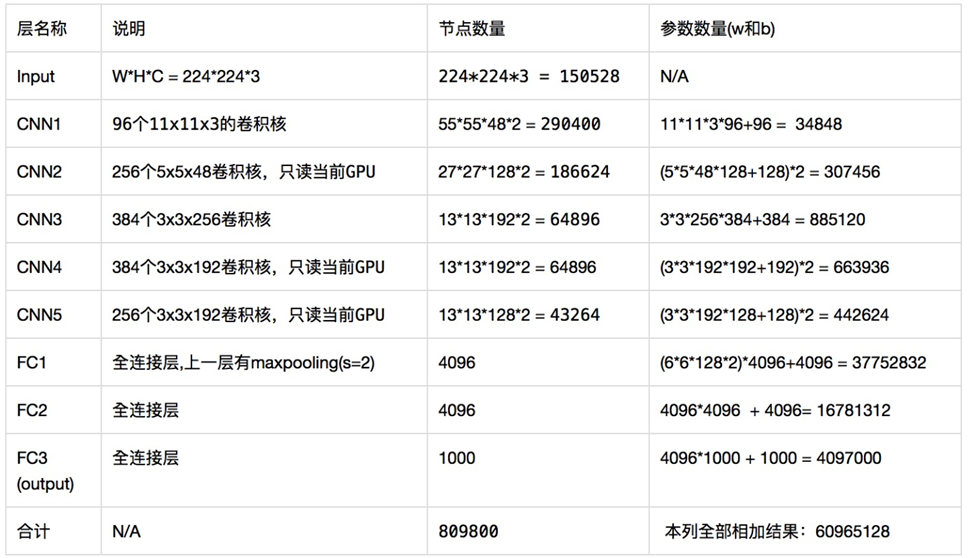

图10 AlexNet模型的拓扑结构及参数数量

        卷积神经网络的训练过程与BP神经网络类似，主要包含以下步骤：

- **前向传播：**输入图像通过卷积层，生成特征图；应用激活函数（如ReLU）、池化操作；重复以上步骤，直到所有卷积和池化层处理完成；将输出扁平化并通过全连接层传递。使用Softmax或其他函数处理最终输出，得到分类或预测。

- **反向传播与优化：**计算损失函数（如交叉熵损失），确定输出与真实标签之间的误差。通过反向传播算法（如梯度下降），沿网络回传误差，更新每一层的权重和偏置。重复迭代上述过程，直到模型收敛或达到预定的迭代次数。

## **8.2 案例1：利用AlexNet预训练模型实时预测摄像头捕获图像类别**

- **创建USB摄像头对象 **

camera = webcam; % Connect to the camera

- **加载AlexNet预训练模型**

nnet = alexnet;  % Load the neural net

- **实时捕获摄像头图像并预测类别 **

while true   
    picture = camera.snapshot;              % 捕获图像    
    picture = imresize(picture,[227,227]);  % 缩放图像

    label = classify(nnet, picture);        % 预测类别标签
       
    image(picture);                         % 显示图像
    title(char(label));                     % 显示类别标签
    drawnow;   
end

## **8.3 案例2：自定义CNN拓扑结构并训练模型**

- **导入训练集数据**

        在当前工作路径下，Dataset文件夹中有一个图像数据集，共包含10个不同类别的物体。考虑到全部类别纳入训练需要花费较长时间，这里仅以其中的两个类别为例。        

categories = {'Dog','Cat'};

CurrentPath = cd;       % 获取当前文件夹路径   
rootFolder = [CurrentPath '\Dataset\cifar10Train'];
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
[trainingSet, validationSet] = splitEachLabel(imds, 2000, 100, 'randomize'); 

- **自定义卷积神经网络结构        **

varSize = 32;
conv1 = convolution2dLayer(5,varSize,'Padding',2,'BiasLearnRateFactor',2);
fc1 = fullyConnectedLayer(16,'BiasLearnRateFactor',2);
fc2 = fullyConnectedLayer(2,'BiasLearnRateFactor',2);

layers = [imageInputLayer([varSize varSize 3]);
          conv1;
          batchNormalizationLayer;
          maxPooling2dLayer(3,'Stride',2);
          reluLayer();
          convolution2dLayer(5,32,'Padding',2,'BiasLearnRateFactor',2);
          batchNormalizationLayer;
          reluLayer();
          averagePooling2dLayer(3,'Stride',2);
          convolution2dLayer(5,64,'Padding',2,'BiasLearnRateFactor',2);
          batchNormalizationLayer;
          reluLayer();
          averagePooling2dLayer(3,'Stride',2);
          fc1;
          reluLayer();
          fc2;
          softmaxLayer()
          classificationLayer()];      

- **设置训练参数        **

opts = trainingOptions('adam', ...
                       'InitialLearnRate', 0.001, ...
                       'LearnRateSchedule', 'piecewise', ...
                       'LearnRateDropFactor', 0.05, ...
                       'LearnRateDropPeriod', 10, ...
                       'L2Regularization', 0.004, ...
                       'MaxEpochs', 50, ...
                       'MiniBatchSize', 100, ...
                       'Verbose', false,...
                       'ValidationData', validationSet,...
                       'ValidationFrequency', 50,...
                       'Plot','training-progress');


- **训练卷积神经网络模型        **

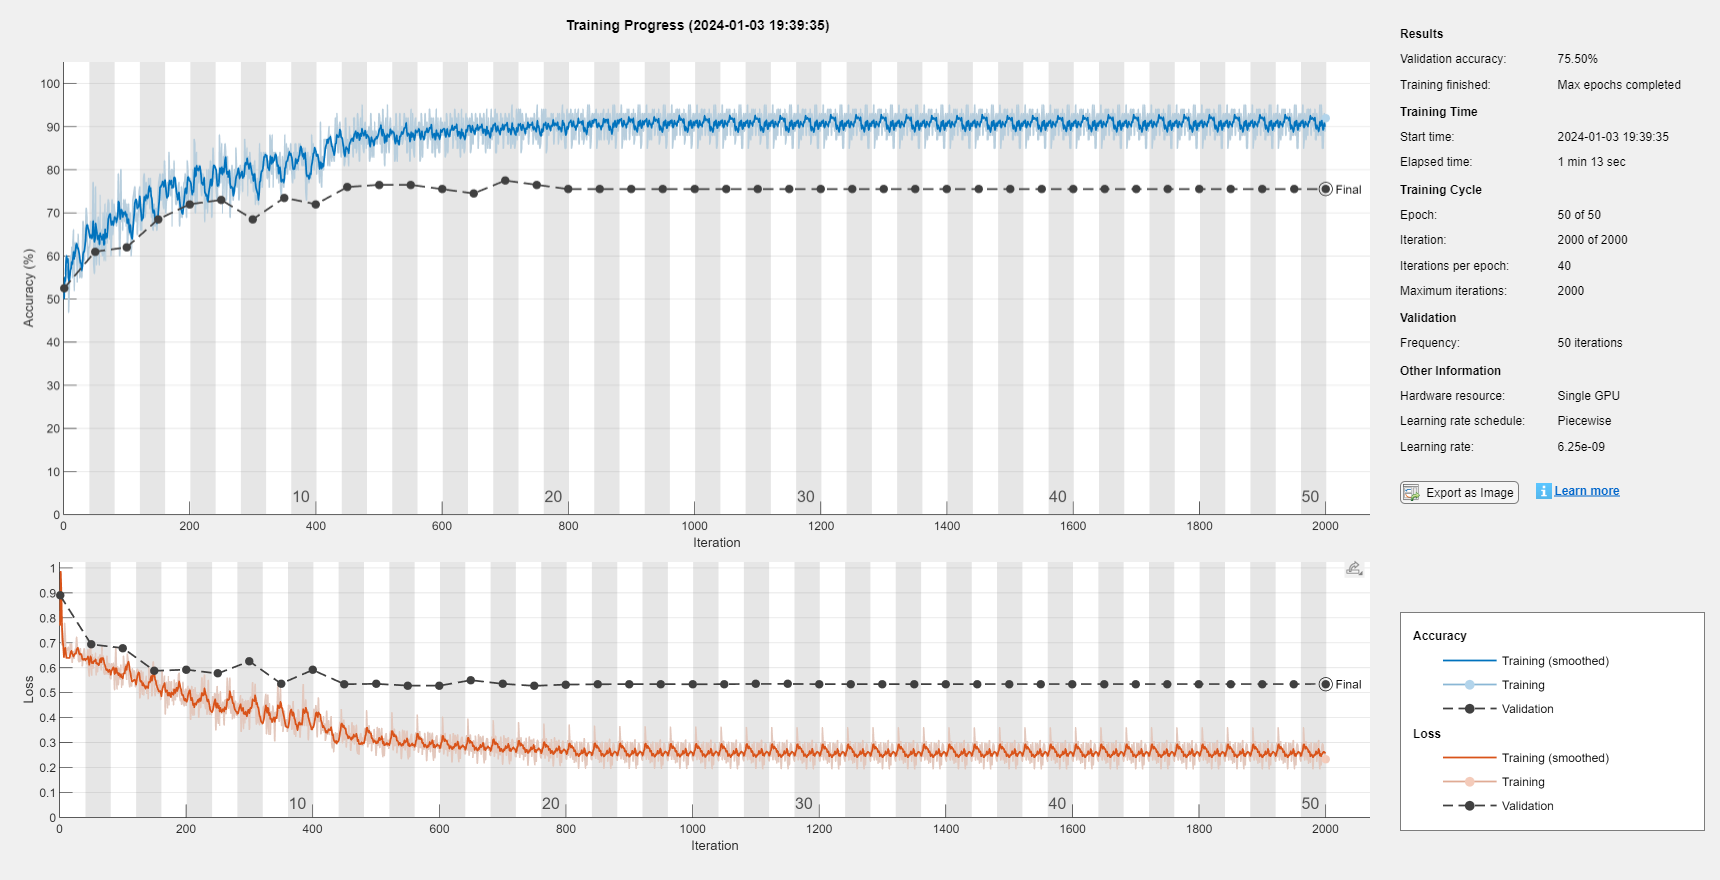

[net, info] = trainNetwork(trainingSet, layers, opts);

- **导入测试集数据        **

rootFolder = [CurrentPath '\Dataset\cifar10Test'];
imds_test = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
[testingSet, ~] = splitEachLabel(imds_test, 1000, 'randomize'); 

- **卷积神经网络模型预测        **

labels = classify(net, testingSet);

- **计算混淆矩阵        **

confMat = confusionmat(testingSet.Labels, labels);
confMat = confMat./sum(confMat,2);
mean(diag(confMat))

ans = 0.7725

## **8.4 案例3：利用AlexNet预训练模型作为特征提取器**

- **导入Alexnet预训练模型        **

net = alexnet;

% 查看Alexnet拓扑结构
net.Layers 

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0

- **导入训练集数据        **

CurrentPath = cd;       % 获取当前文件夹路径   
rootFolder = [CurrentPath '\Dataset\cifar10Train'];
categories = {'Deer','Dog','Frog','Cat'};   % 为了减少计算量，仅选取四个类别
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imds.ReadFcn = @readFunctionTrain;

M = 100;
[trainingSet, ~] = splitEachLabel(imds, M, 'randomize'); 

- **利用Alexnet抽取训练集的特征        **

% 指定提取到'conv1'层的输出特征图
featureLayer = 'conv1';
trainingFeatures = activations(net, trainingSet, featureLayer);

% 特征图可视化
figure
for i = 1:96
    subplot(12, 8, i)
    imshow(trainingFeatures(:, :, i, 1))
end

% 将4-D矩阵转换为二维矩阵
P_train = reshape(trainingFeatures(:), [], size(trainingFeatures,4));
P_train = P_train';

T_train = trainingSet.Labels;

- **利用抽取的Alexnet特征训练Naive Bayes模型        **

classifier = fitcnb(P_train(:,1:100:end), T_train);

- **导入测试集数据        **

rootFolder = [CurrentPath '\Dataset\cifar10Test'];
testSet = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
testSet.ReadFcn = @readFunctionTrain;

N = 100;
[testSets, ~] = splitEachLabel(testSet, N, 'randomize'); 

- **利用Alexnet抽取测试集的特征        **

testFeatures = activations(net, testSets, featureLayer);

P_test = reshape(testFeatures(:), [], size(testFeatures,4));
P_test = P_test';
T_test = testSets.Labels;

- **Naive Bayes模型预测**        

T_sim = predict(classifier, P_test(:,1:100:end));

- **计算混淆矩阵        **

confMat = confusionmat(T_test, T_sim);
confMat = confMat./sum(confMat,2);
mean(diag(confMat))

ans = 0.4600

## **Appendix：读取图像子函数**

function I = readFunctionTrain(filename)

    I = imread(filename);       % 读取图像
    I = imresize(I, [227 227]); % 缩放图像

end